# 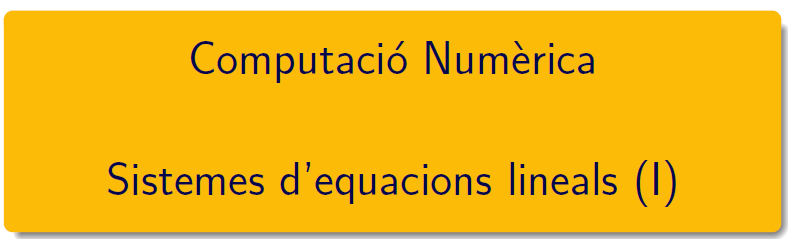

================================================================================

# TEMA 2 Àlgebra lineal numèrica (I)

## Introducció

A més a més dels exercicis d'aquest script teniu disponibles exercicis en el document Guia-CNLab2-3.pdf i en el document CN_full2.pdf, els podeu trobar en el campus virtual. 

## Mètodes iteratius estacionaris 

Són els mètodes de Jacobi, de Gauss-Seidel i de sobrerelaxació (SOR)


$$Ax=b \Longleftrightarrow x^{k+1}=B\,x^{k}+c\,,\quad \forall\ k\ge0\,.$$


### Submatrius D, L i U de la matriu A

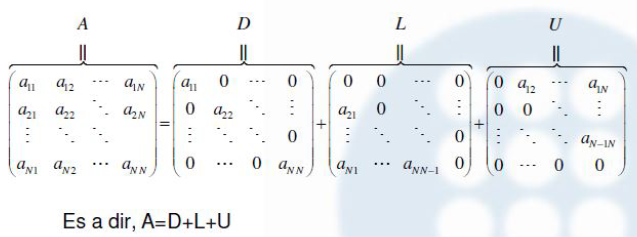   

**Exercici 1.** Obteniu les submatrius per a la matriu $A=\left( \begin{array}{rrr}
1 & 0 & 1 \\
-1 & 1 & 0\\
1 & 2 & -3
\end{array} \right)$

A = [1 0 1; -1 1 0; 1 2 -3];
D = diag(diag(A))   % dos vegades diag per deixar en forma matriu
L = tril(A-D), U = triu(A-D)

**Exercici 2. **Determineu  les matrius d'iteració del mètode de Jacobi i del mètode de Gauss-Seidel del sistema Ax=b donat per 


$$A=\left( \begin{array}{rrr}
1 & 0 & 1 \\
-1 & 1 & 0\\
1 & 2 & -3
\end{array} \right)\quad\quad
b=\left(\begin{array}{r}   4\\ 1\\-4\end{array} \right) 
\quad \Longrightarrow \quad
x=\left(\begin{array}{r}   1\\ 2\\3\end{array} \right) $$


b = [4 1 -4]'; x = [1 2 3]';

Matrius de Jacobi

DI = inv(D);    % inversa
BJ = -DI*(L+U);
cJ = DI*b;
rhoJ = abs(eigs(BJ,1))  % < 1 per tant convergent

rhoJ =       0.94444


jacobifun(A,b)

El mètode és convergent, en k = 100, el residu és 0.02616 i el vector solució és:


ans =       0.99935
       2.0092
       3.0087


Matrius de Gauss-Seidel

DI = inv(D+L);
Bgs = -DI*U;
cgs = DI*b;
rhogs = abs(eigs(Bgs,1))    % == 1 divergent no millorarà

rhogs =      1


gseidelfun(A,b)

mètode de Gauss-Seidel divergent

Matrius de SOR - Gauss-Sseidel

w =0.8;         % Aquest valor ha de ser a l'interval (0,2), w = 1 és Gauss-Seidel
C = inv(D+w*L);
Bwgs = C*((1-w)*D-w*U);
cwgs = w*C*b;
sor_gseidelfun(A,b,w)

El mètode és convergent, en k = 13, el residu és 7.713e-07 i el vector solució és:


ans =             1
            2
            3


### Radi espectral 

Definició i propietats en el document bloc 0 (pàg 16, bloc 0)

Càlcul de valors i vectors propis en Matlab®: consulteu [eigs ](https://www.mathworks.com/help/matlab/ref/eigs.html)i [eig](https://es.mathworks.com/help/matlab/ref/eig.html) 

H = hilb(4)
vaps = eig(H), rho = abs(eigs(H,1)) % radi = vap de mòdul màxim

rho =        1.5002


rhoJ = abs(eigs(BJ,1))      % radi = vap de mòdul màxim

rhoJ =       0.94444


rhogs = abs(eigs(Bgs,1))

rhogs =      1


rhoW = abs(eigs(Bwgs,1))

rhoW =       0.28699


### Pràctica 1

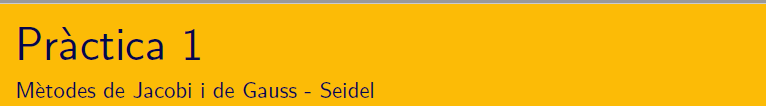

Escriviu un programa que implementi els algoritmes de Jacobi, Gauss - Seidel i SOR. Proveu-ho per

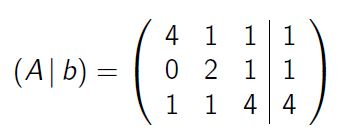

Mètode de Jacobi

A = [4 1 1; 0 2 1; 1 1 4]; b = [1 1 4]';
if rhoJ < 1
    k = 0;
    x = zeros(size(b));
    r = norm(A*x-b,1);
    while (k < 10 && r > 5.0e-5)
        k = k + 1;
        x = BJ*x+cJ;
        r = norm(A*x-b,1);
    end
    fprintf('mètode de Jacobi convergent')
    x
else
    fprintf('mètode de Jacobi divergent')
end

Mètode de Gauss-Seidel   

if rhogs < 1    
    k = 0;
    x = zeros(size(b));
    r = norm(A*x-b,1);
    while (k < 10 && r > 5.0e-5)
        k = k + 1;
        x = Bgs*x+cgs;
        r = norm(A*x-b,1);
    end
    fprintf('mètode de Gauss-Seidel convergent')
    x
else
    fprintf('mètode de Gaus-Seidel divergent')
end

Mètode de SOR - Gauss-Seidel

if rhoW < 1    
    k = 0;
    x = zeros(size(b));
    r = norm(A*x-b,1);
    while (k < 10 && r > 5.0e-5)
        k = k + 1;
        x = Bwgs*x+cwgs;
        r = norm(A*x-b,1);
    end
    fprintf('mètode de SOR-Gauss-Seidel convergent')
    x
else
    fprintf('mètode de SOR-Gaus-Seidel divergent')
end

### Pràctica 2

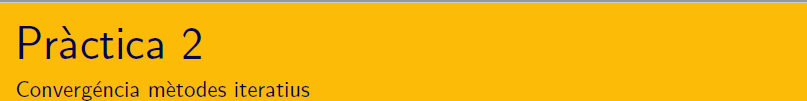

Introduiu un test de convergència per als algoritmes de Jacobi, de Gauss - Seidel i SOR. Proveu-lo per

     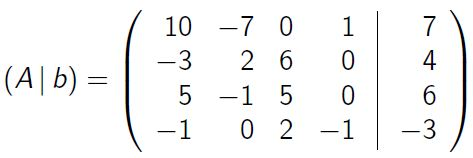      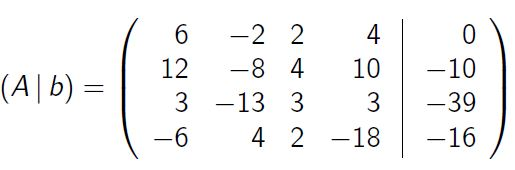

A = [4 1 1; 0 2 1; 1 1 4]; b = [1 1 4]';
jacobifun(A,b)

El mètode és convergent, en k = 21, el residu és 3.179e-06 i el vector solució és:


ans =    2.1193e-07
   2.1193e-07
            1


gseidelfun(A,b)

El mètode és convergent, en k = 9, el residu és 2.914e-06 i el vector solució és:


ans =   -6.8446e-07
   1.7614e-07
            1


w = 1.2;
sor_gseidelfun(A,b,w)

El mètode és convergent, en k = 13, el residu és 3.102e-06 i el vector solució és:


ans =    6.6406e-07
   1.0894e-07
            1


A = [10 -7 0 1; -3 2 6 0; 5 -1 5 0; -1 0 2 -1]; b = [7 4 6 -3]';
jacobifun(A,b)

mètode de Jacobi divergent

gseidelfun(A,b)

mètode de Gauss-Seidel divergent

sor_gseidelfun(A,b,w)

mètode de SOR-Gauss-Seidel divergent

A = [6 -2 2 4; 12 -8 4 10; 3 -13 3 3; -6 4 2 -18]; b =[0 -10 -39 -16]';
jacobifun(A,b)

mètode de Jacobi divergent

gseidelfun(A,b)

El mètode és convergent, en k = 100, el residu és 0.003538 i el vector solució és:


ans =        1.0022
       2.9992
      -2.0042
      0.99862


sor_gseidelfun(A,b,w)

El mètode és convergent, en k = 100, el residu és 0.003586 i el vector solució és:


ans =        1.0024
       2.9991
      -2.0048
      0.99847


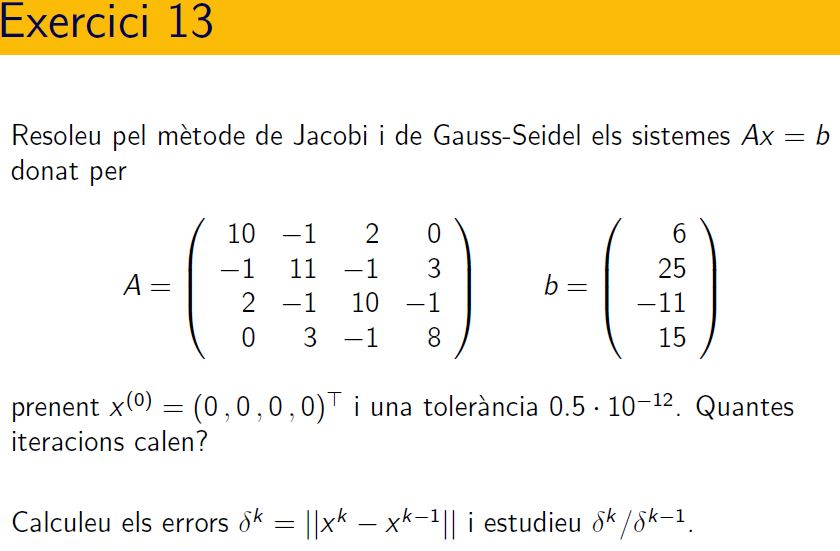

% Realitzat al LAB 4
A = [10 -1 2 0; -1 11 -1 3; 2 -1 10 -1; 0 3 -1 8]; b = [6 25 -11 15]';
tol = 0.5e-12; n = 500;
jacobifun(A,b,tol,n)
gseidelfun(A,b,tol,n)
linsolve(A,b)

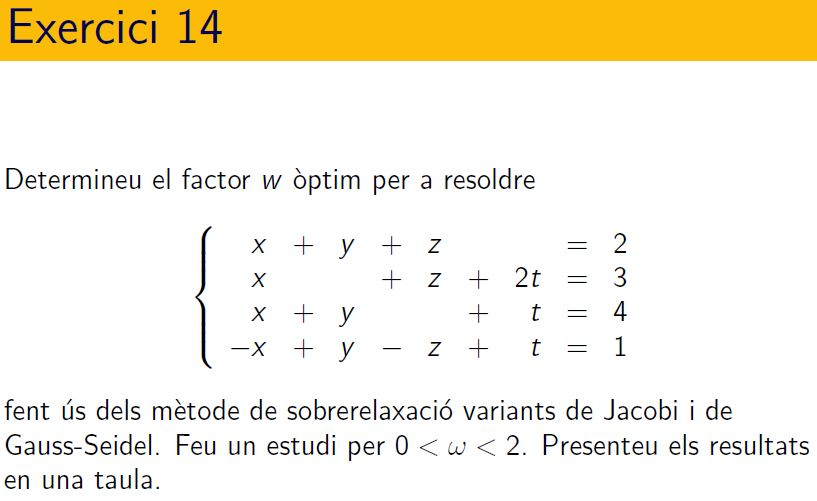

% Realitzat al LAB 4


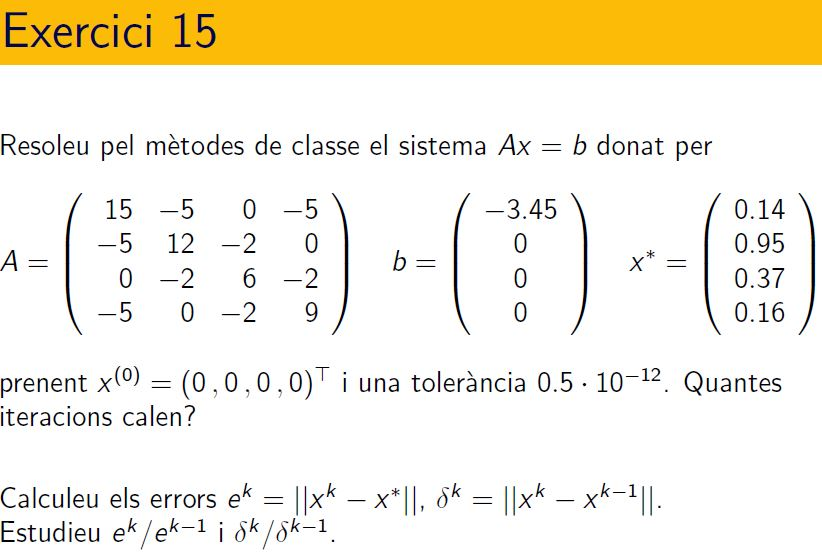

% Realitzat al LAB 4

En una primera aproximació determineu les 10 primeres iteracions dels tres mètodes i estudieu el vector residu per cada mètode.

Introduiu un test de convergència per als algoritmes de Jacobi, de Gauss - Seidel i SOR. Proveu-lo per


$$$$A=\left( \begin{array}{rrrr}
10 & -1 & 2 & 0 \\
-1 & 11 & -1 & 3\\
2 & -1 & 10 & -1\\
0 & 3 & -1 & 8
\end{array} \right)\quad\quad
b=\left(\begin{array}{r}   6\\ 25\\-11\\ 15\end{array} \right)
\qquad
x=\left(\begin{array}{r}   1\\ 2\\-1\\ 1\end{array} \right)$$
$$


clearvars
A = [10 -1 2 0; -1 11 -1 3; 2 -1 10 -1; 0 3 -1 8]; b = [6 25 -11 15]';
jacobifun(A,b)
gseidelfun(A,b)
sor_gseidelfun(A,b,1.025)

## Mètodes iteratius no estacionaris 

Consulteu en la documentació de MATLAB® - [Iterative Methods for Linear Systems](https://es.mathworks.com/help/matlab/math/iterative-methods-for-linear-systems.html)

`Document preparat per M. Àngela Grau Gotés, 3 de març de 2021`